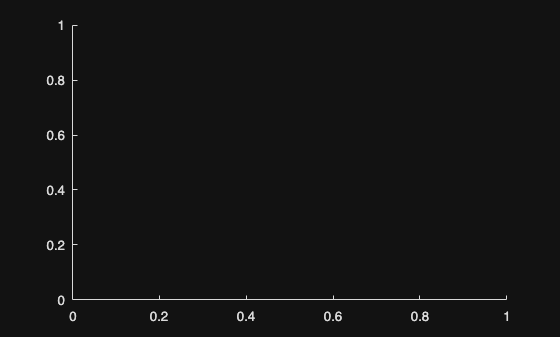

% run_a_star_3d_mapB.m
clear; clc; close all;

% --- set your repo root ABSOLUTELY ---
repoRoot = '/Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning';  % <- adjust if needed
assert(isfolder(repoRoot), 'Bad repoRoot: %s', repoRoot);

% --- paths ---
addpath(genpath(fullfile(repoRoot,'utils')));
addpath(genpath(fullfile(repoRoot,'global_planner')));

% --- load 3D map (MAP B) ---
mapLabel = 'mapB_20x30x30';
mapFile  = fullfile(repoRoot,'utils','data','map',[mapLabel '.mat']);
assert(isfile(mapFile), 'Map not found: %s', mapFile);
S = load(mapFile);
grid_map = S.grid_map;

% --- plan with a_star_3d ---
start = [3, 2, 2];        % [row, col, z]
goal  = [18, 29, 25];

tic;
[path, flag, cost, expand] = a_star_3d(grid_map, start, goal);
runtime = toc;

% --- visualize ---
clf; hold on;

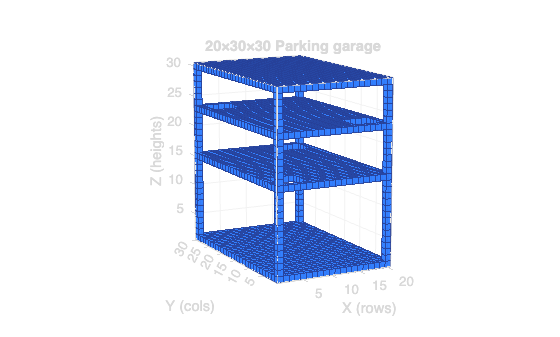

plot_grid_3d(grid_map);

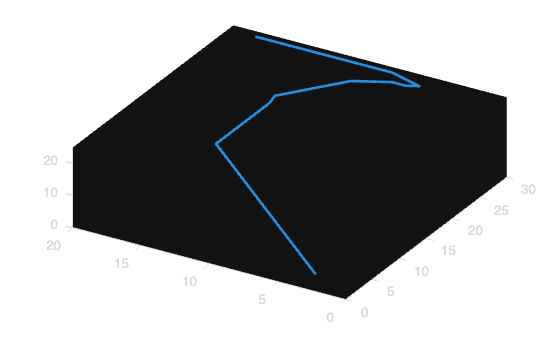

if ~isempty(path)
    plot3(path(:,2), path(:,1), path(:,3), '-', 'LineWidth', 2);
end

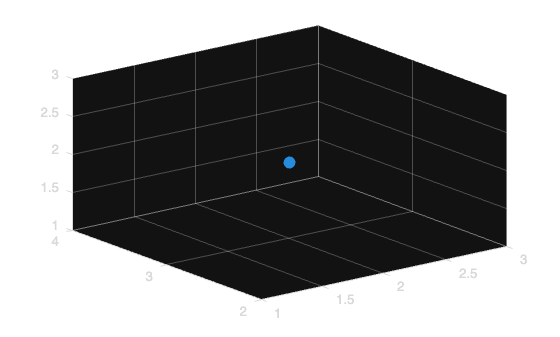

scatter3(start(2),start(1),start(3),80,'filled');

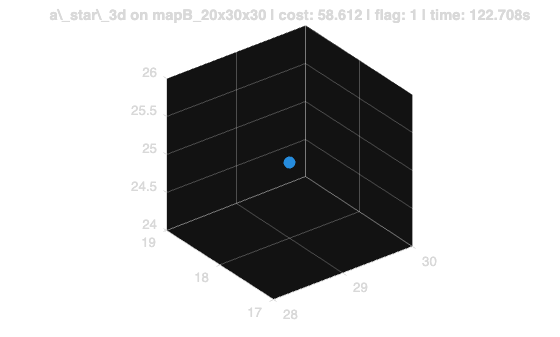

scatter3(goal(2),goal(1),goal(3),80,'filled');
title(sprintf('a\\_star\\_3d on %s | cost: %.3f | flag: %d | time: %.3fs', ...
      mapLabel, cost, flag, runtime), 'Interpreter','none');
axis vis3d; grid on; view(3); hold off;

%% ---- SAVE RESULTS FOR PRESENTATION ----
outDir = fullfile(repoRoot,'results');
if ~exist(outDir,'dir'), mkdir(outDir); end
stamp = datestr(now,'yyyymmdd_HHMMSS');

% 1) Path as CSV
if ~isempty(path)
    step   = (0:size(path,1)-1).';
    d      = sqrt(sum(diff(path,1,1).^2,2));
    cumlen = [0; cumsum(d)];
    Tpath  = table(step, path(:,1), path(:,2), path(:,3), cumlen, ...
                   'VariableNames', {'step','row','col','z','cumlen'});
    pathCsv = fullfile(outDir, sprintf('path_a_star_3d_%s_%s.csv', mapLabel, stamp));
    writetable(Tpath, pathCsv);
end

% 2) Expand as CSV (if available)
if exist('expand','var') && ~isempty(expand)
    if size(expand,2)==1
        [er, ec, ez] = ind2sub(size(grid_map), expand(:));
    elseif size(expand,2)==3
        er = expand(:,1); ec = expand(:,2); ez = expand(:,3);
    else
        er = []; ec = []; ez = [];
        warning('Unknown expand shape; skipping export.');
    end
    if ~isempty(er)
        Texpand = table(er,ec,ez, 'VariableNames', {'row','col','z'});
        expCsv = fullfile(outDir, sprintf('expand_a_star_3d_%s_%s.csv', mapLabel, stamp));
        writetable(Texpand, expCsv);
    end
end

% 3) Run summary (append to log)
summary = table( ...
    string('a_star_3d'), string(mapLabel), ...
    start(1),start(2),start(3), goal(1),goal(2),goal(3), ...
    size(path,1), cost, flag, size(expand,1), runtime, string(stamp), ...
    'VariableNames', {'planner','map','start_r','start_c','start_z', ...
                      'goal_r','goal_c','goal_z','path_steps','cost', ...
                      'flag','nodes_expanded','runtime_s','stamp'});
logCsv = fullfile(outDir,'runs_log.csv');
if isfile(logCsv)
    writetable(summary, logCsv, 'WriteMode','Append');
else
    writetable(summary, logCsv);
end

% 4) Save the figure
figPdf = fullfile(outDir, sprintf('viz_a_star_3d_%s_%s.pdf', mapLabel, stamp));
figPng = fullfile(outDir, sprintf('viz_a_star_3d_%s_%s.png', mapLabel, stamp));
exportgraphics(gcf, figPdf, 'ContentType','vector');
exportgraphics(gcf, figPng, 'Resolution', 300);


% 5) Save raw MATLAB data
matFile = fullfile(outDir, sprintf('run_a_star_3d_%s_%s.mat', mapLabel, stamp));
save(matFile, 'grid_map','path','cost','flag','expand','start','goal','runtime');

% Print what we saved
fprintf('Saved:\n');

Saved:


if exist('pathCsv','var'), fprintf('  %s\n', pathCsv); end

  /Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/results/path_a_star_3d_mapB_20x30x30_20250913_141057.csv


if exist('expCsv','var'),  fprintf('  %s\n', expCsv);  end

  /Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/results/expand_a_star_3d_mapB_20x30x30_20250913_141057.csv


fprintf('  %s\n  %s\n  %s\n', figPdf, figPng, matFile);

  /Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/results/viz_a_star_3d_mapB_20x30x30_20250913_141057.pdf
  /Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/results/viz_a_star_3d_mapB_20x30x30_20250913_141057.png
  /Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/results/run_a_star_3d_mapB_20x30x30_20250913_141057.mat
